clear
% Pararameters of affine transformation model Y = A*X+b
A = ...
  [1 1;
   0 1];

b = [0; 1];

% Mean and Covariance of X
mu_x = [3; -6];

Sigma_x = ...
  [4 2;
   2 5];

plot

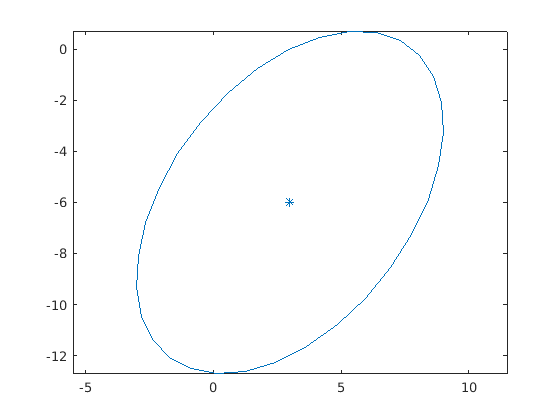

xy = sigmaEllipse2D(mu_x, Sigma_x);
figure(1);
h1 = plot(xy(1,:), xy(2,:));
axis equal
hold on
plot(mu_x(1), mu_x(2), '*', 'color', h1.Color);

% Mean and Covariance of Y = A*X+b
[mu_y, Sigma_y] = affineGaussianTransform(mu_x, Sigma_x, A, b);

plot2

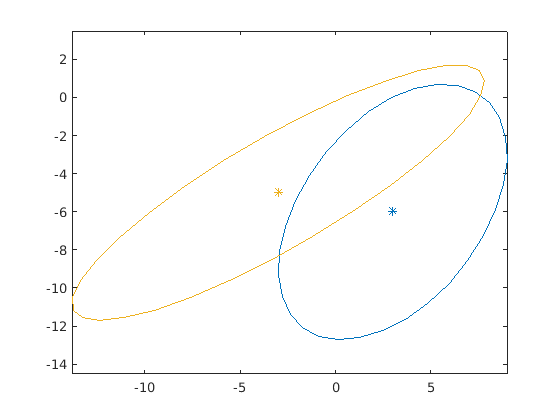

xy2 = sigmaEllipse2D(mu_y, Sigma_y);
h1 = plot(xy2(1,:), xy2(2,:));
plot(mu_y(1), mu_y(2), '*', 'color', h1.Color);